clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';
Var4='HFX';

%%%% Para el primero %%%% 
    Ar1=['6'];
    Ar2=['6_2'];
    un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
    t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
    wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
    HFX= cat (2,squeeze(ncread(Ar1,Var4)),squeeze(ncread(Ar2,Var4)));
    puntosz=99;                           %Tamaño Vertical de malla
    gravedad=1.352;
    %G=5;  %Numero de niveles
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    un(:,:,37)=[];
    t(:,:,37)=[];
    wn(:,:,37)=[];
    HFX(:,37)=[];
    un(:,:,37)=[];
    t(:,:,37)=[];
    wn(:,:,37)=[];
    HFX(:,37)=[];
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind1=sqrt((u.^2)+(w.^2));
    uprom1 = mean(u,1);                 %Promedio en X
    uprom1 = repmat(uprom1,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim1 = u-uprom1;                  %Obtenemos la fluctuacion 
    tprom1 = mean(t,1);
    tprom1 = repmat(tprom1,length(wn(:,1,1)),1);
    tprim1 = t-tprom1;
    wprom1 = mean(w,1);
    wprom1 = repmat(wprom1,length(wn(:,1,1)),1);
    wprim1 = w-wprom1;
    windprom1=mean(wind1,1);
    windprom1=repmat(windprom1,length(wn(:,1,1)),1);
    windprim1=wind1-windprom1;
    HFX1= squeeze(mean(HFX,1))';
    clear u t w wn un HFX
    

%%%% Para el segundo %%%% 
    Ar1=['7'];
    un = squeeze(ncread(Ar1,Var1));
    t = squeeze(ncread(Ar1,Var2))+100;
    wn = squeeze(ncread(Ar1,Var3));
    HFX= squeeze(ncread(Ar1,Var4));
    gravedad=1.352;
    %G=5;  %Numero de niveles
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind2=sqrt((u.^2)+(w.^2));
    uprom2 = mean(u,1);                 %Promedio en X
    uprom2 = repmat(uprom2,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim2 = u-uprom2;                  %Obtenemos la fluctuacion 
    tprom2 = mean(t,1);
    tprom2 = repmat(tprom2,length(wn(:,1,1)),1);
    tprim2 = t-tprom2;
    wprom2 = mean(w,1);
    wprom2 = repmat(wprom2,length(wn(:,1,1)),1);
    wprim2 = w-wprom2;
    windprom2=mean(wind2,1);
    windprom2=repmat(windprom2,length(wn(:,1,1)),1);
    windprim2=wind2-windprom2;
    HFX2= squeeze(mean(HFX,1))';
    clear u t w wn un ejex1 ejex2 timebar HFX

%%%% Para el tercero %%%% 
    Ar1=['8'];
    un = squeeze(ncread(Ar1,Var1));
    t = squeeze(ncread(Ar1,Var2))+100;
    wn = squeeze(ncread(Ar1,Var3));
    HFX= squeeze(ncread(Ar1,Var4));
    gravedad=1.352;
    %G=5;  %Numero de niveles
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind3=sqrt((u.^2)+(w.^2));
    uprom3 = mean(u,1);                 %Promedio en X
    uprom3 = repmat(uprom3,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim3 = u-uprom3;                  %Obtenemos la fluctuacion 
    tprom3 = mean(t,1);
    tprom3 = repmat(tprom3,length(wn(:,1,1)),1);
    tprim3 = t-tprom3;
    wprom3 = mean(w,1);
    wprom3 = repmat(wprom3,length(wn(:,1,1)),1);
    wprim3 = w-wprom3;
    windprom3=mean(wind3,1);
    windprom3=repmat(windprom3,length(wn(:,1,1)),1);
    windprim3=wind3-windprom3;
    HFX3= squeeze(mean(HFX,1))';
    clear u t w wn un HFX

sz= size(tprom1(:,:,1:48));
tprim1= reshape(tprim1(:,:,1:48),500,sz(2),[],8);
uprim1= reshape(uprim1(:,:,1:48),500,sz(2),[],8);
wprim1= reshape(wprim1(:,:,1:48),500,sz(2),[],8);
HFX1=reshape(HFX1(1:48), 6, []);

tprim2= reshape(tprim2(:,:,1:48),1000,sz(2),[],8);
uprim2= reshape(uprim2(:,:,1:48),1000,sz(2),[],8);
wprim2= reshape(wprim2(:,:,1:48),1000,sz(2),[],8);
HFX2=reshape(HFX2(1:48), 6, []);

tprim3= reshape(tprim3(:,:,1:48),2000,sz(2),[],8);
uprim3= reshape(uprim3(:,:,1:48),2000,sz(2),[],8);
wprim3= reshape(wprim3(:,:,1:48),2000,sz(2),[],8);
HFX3=reshape(HFX3(1:48), 6, []);

ur1=rms(uprim1,3);
ur2=rms(uprim2,3);
ur3=rms(uprim3,3);
ur1= squeeze(rms(ur1,1));
ur2= squeeze(rms(ur2,1));
ur3= squeeze(rms(ur3,1));
um1=rms(wprim1,3);
um2=rms(wprim2,3);
um3=rms(wprim3,3);
um1= squeeze(rms(um1,1));
um2= squeeze(rms(um2,1));
um3= squeeze(rms(um3,1));

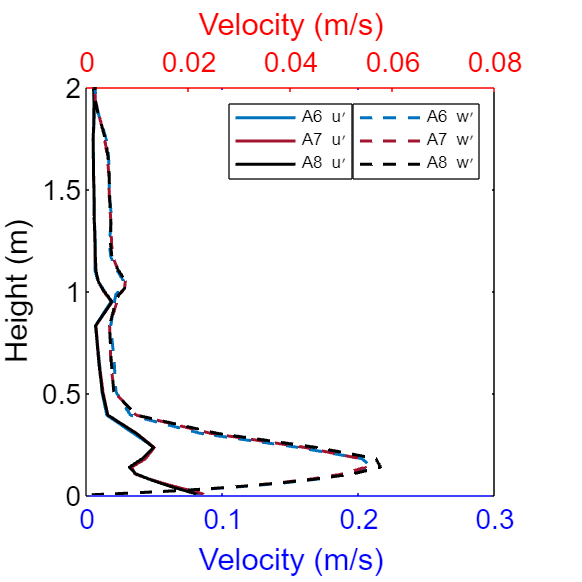

figure;
set(gcf, 'Position', [100, 100, 600, 600]); % Aumentar el tamaño de la figura
% Eje original (eje inferior)
ax1 = axes;
p(1) = plot(ax1,ur1(:,2),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
ylabel(ax1, 'Height (m)');
xlabel('Velocity (m/s)')
% Personalizar el primer eje
ax1.XColor = 'blue';
ax1.YColor = 'black';
p(2) = plot(ax1,ur2(:,2),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ax1,ur3(:,2),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 u\prime','A7 u\prime','A8 u\prime'},'Location', 'north');
xlim(ax1, [0, 0.3]);
% Añadir un segundo eje (eje superior)
ax2 = axes('Position', ax1.Position, 'XAxisLocation', 'top', 'YAxisLocation', 'left', ...
           'Color', 'none');
hold(ax2, 'on');
p(4) = plot(ax2,um1(:,2),ejez./1000,'--', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
p(5) = plot(ax2,um2(:,2),ejez./1000,'--', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(6) = plot(ax2,um3(:,2),ejez./1000,'--', 'LineWidth', 1.5, 'Color','k');hold on;
% Personalizar el segundo eje
ax2.XColor = 'red';
ax2.YTick = []; % Opcional: eliminar las marcas en el eje Y del segundo eje
% % Sincronizar límites en el eje Y para que se alineen visualmente
linkaxes([ax1, ax2], 'y');
% % Crear una sola leyenda combinada para ambos gráficos
legend({'A6 w\prime','A7 w\prime','A8 w\prime'},'Location', 'northeast');
xlabel('Velocity (m/s)')
xlim(ax2, [0, 0.08]);
ylim([0, 2]);
hold off
ax1.XAxis.FontSize = 14; % Eje izquierdo
ax2.XAxis.FontSize = 14; % Eje derecho
ax1.YAxis.FontSize = 14;    % Eje X
ax2.YAxis.FontSize = 14;    % Eje X
ax1.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
ax2.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]

% saveas(gca,'Figure4A.png');

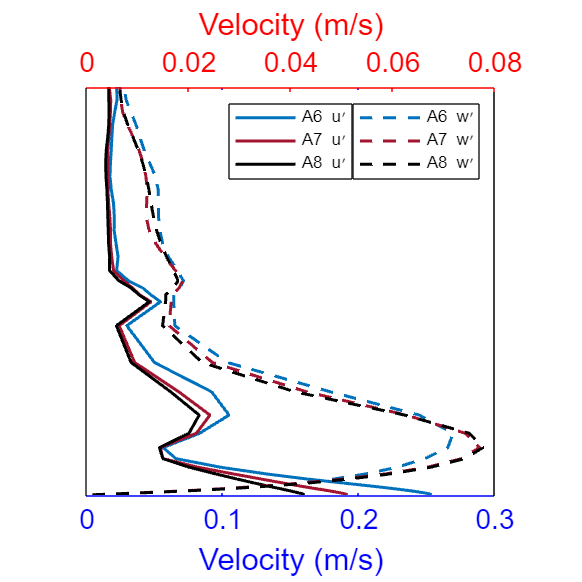

figure;
set(gcf, 'Position', [100, 100, 600, 600]); % Aumentar el tamaño de la figura
% Eje original (eje inferior)
ax1 = axes;
p(1) = plot(ax1,ur1(:,5),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (m)');
xlabel('Velocity (m/s)')
% Personalizar el primer eje
ax1.XColor = 'blue';
ax1.YColor = 'black';
p(2) = plot(ax1,ur2(:,5),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ax1,ur3(:,5),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 u\prime','A7 u\prime','A8 u\prime'},'Location', 'north');
xlim(ax1, [0, 0.3]);
% Añadir un segundo eje (eje superior)
ax2 = axes('Position', ax1.Position, 'XAxisLocation', 'top', 'YAxisLocation', 'left', ...
           'Color', 'none');
hold(ax2, 'on');
p(4) = plot(ax2,um1(:,5),ejez./1000,'--', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
p(5) = plot(ax2,um2(:,5),ejez./1000,'--', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(6) = plot(ax2,um3(:,5),ejez./1000,'--', 'LineWidth', 1.5, 'Color','k');hold on;
% Personalizar el segundo eje
ax2.XColor = 'red';
ax2.YTick = []; % Opcional: eliminar las marcas en el eje Y del segundo eje
% % Sincronizar límites en el eje Y para que se alineen visualmente
linkaxes([ax1, ax2], 'y');
% % Crear una sola leyenda combinada para ambos gráficos
legend({'A6 w\prime','A7 w\prime','A8 w\prime'},'Location', 'northeast');
xlabel('Velocity (m/s)')
xlim(ax2, [0, 0.08]);
ylim([0, 2]);
hold off
ax1.XAxis.FontSize = 14; % Eje izquierdo
ax2.XAxis.FontSize = 14; % Eje derecho
ax1.YAxis.FontSize = 14;    % Eje X
ax2.YAxis.FontSize = 14;    % Eje X
ax1.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
ax2.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
set(ax1, 'YTick', [])
set(ax2, 'YTick', [])

% saveas(gca,'Figure4B.png');

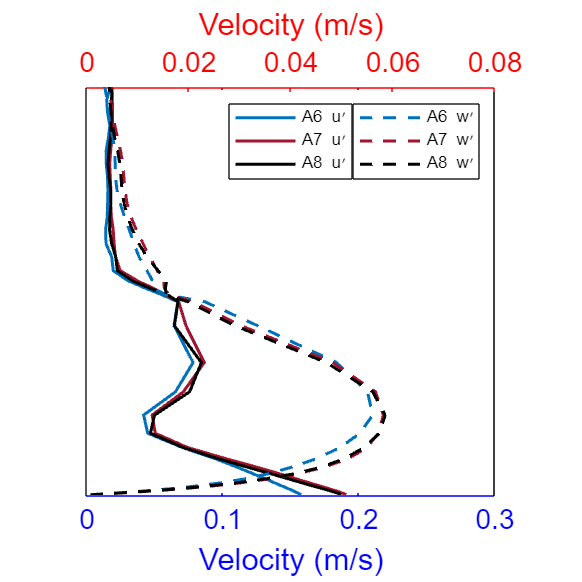

figure;
set(gcf, 'Position', [100, 100, 600, 600]); % Aumentar el tamaño de la figura
% Eje original (eje inferior)
ax1 = axes;
p(1) = plot(ax1,ur1(:,8),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (km)');
xlabel('Velocity (m/s)')
% Personalizar el primer eje
ax1.XColor = 'blue';
ax1.YColor = 'black';
p(2) = plot(ax1,ur2(:,8),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ax1,ur3(:,8),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 u\prime','A7 u\prime','A8 u\prime'},'Location', 'north');
xlim(ax1, [0, 0.3]);
% Añadir un segundo eje (eje superior)
ax2 = axes('Position', ax1.Position, 'XAxisLocation', 'top', 'YAxisLocation', 'left', ...
           'Color', 'none');
hold(ax2, 'on');
p(4) = plot(ax2,um1(:,8),ejez./1000,'--', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
p(5) = plot(ax2,um2(:,8),ejez./1000,'--', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(6) = plot(ax2,um3(:,8),ejez./1000,'--', 'LineWidth', 1.5, 'Color','k');hold on;
% Personalizar el segundo eje
ax2.XColor = 'red';
ax2.YTick = []; % Opcional: eliminar las marcas en el eje Y del segundo eje
% % Sincronizar límites en el eje Y para que se alineen visualmente
linkaxes([ax1, ax2], 'y');
% % Crear una sola leyenda combinada para ambos gráficos
legend({'A6 w\prime','A7 w\prime','A8 w\prime'},'Location', 'northeast');
xlabel('Velocity (m/s)')
xlim(ax2, [0, 0.08]);
ylim([0, 2]);
hold off
ax1.XAxis.FontSize = 14; % Eje izquierdo
ax2.XAxis.FontSize = 14; % Eje derecho
ax1.YAxis.FontSize = 14;    % Eje X
ax2.YAxis.FontSize = 14;    % Eje X
ax1.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
ax2.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
set(ax1, 'YTick', [])
set(ax2, 'YTick', [])

% saveas(gca,'Figure4C.png');

HF1= squeeze(mean(HFX1,1));
HF2= squeeze(mean(HFX2,1));
HF3= squeeze(mean(HFX3,1));
ur1=5940.*rms((wprim1.*tprim1),3);
ur2=5940.*rms((wprim2.*tprim2),3);
ur3=5940.*rms((wprim3.*tprim3),3);
ur1= squeeze(rms(ur1,1));
ur2= squeeze(rms(ur2,1));
ur3= squeeze(rms(ur3,1));
um1=rms((tprim1.*tprim1),3);
um2=rms((tprim2.*tprim2),3);
um3=rms((tprim3.*tprim3),3);
um1= squeeze(rms(um1,1));
um2= squeeze(rms(um2,1));
um3= squeeze(rms(um3,1));

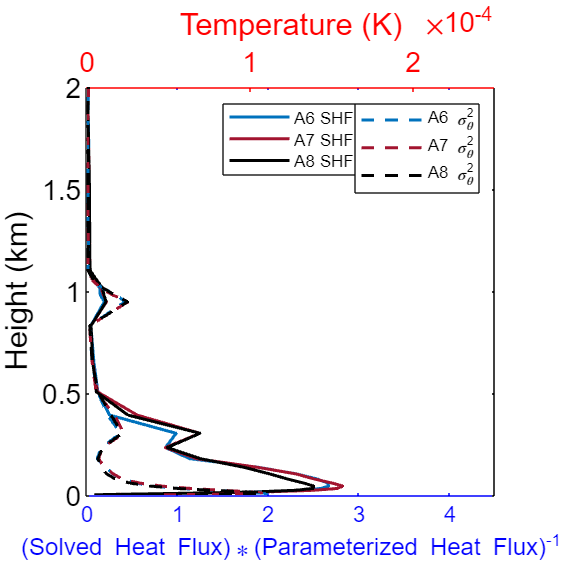

figure;
set(gcf, 'Position', [100, 100, 600, 600]); % Aumentar el tamaño de la figura
% Eje original (eje inferior)
ax1 = axes;
p(1) = plot(ax1,ur1(:,2)./HF1(2),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
ylabel(ax1, 'Height (km)');
% Personalizar el primer eje
ax1.XColor = 'blue';
ax1.YColor = 'black';
p(2) = plot(ax1,ur2(:,2)./HF2(2),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ax1,ur3(:,2)./HF3(2),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 SHF','A7 SHF','A8 SHF'},'Location', 'north');
xlim(ax1, [0, 4.5]);
xlabel('(Solved Heat Flux)\ast(Parameterized Heat Flux)^{-1}', 'Color', 'b');
% Añadir un segundo eje (eje superior)
ax2 = axes('Position', ax1.Position, 'XAxisLocation', 'top', 'YAxisLocation', 'left', ...
           'Color', 'none');
hold(ax2, 'on');
p(4) = plot(ax2,um1(:,2),ejez./1000,'--', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
p(5) = plot(ax2,um2(:,2),ejez./1000,'--', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(6) = plot(ax2,um3(:,2),ejez./1000,'--', 'LineWidth', 1.5, 'Color','k');hold on;
% Personalizar el segundo eje
ax2.XColor = 'red';
ax2.YTick = []; % Opcional: eliminar las marcas en el eje Y del segundo eje
% % Sincronizar límites en el eje Y para que se alineen visualmente
linkaxes([ax1, ax2], 'y');
% % Crear una sola leyenda combinada para ambos gráficos
legend({'A6 \sigma_{\theta}^2','A7 \sigma_{\theta}^2','A8 \sigma_{\theta}^2'},'Location', 'northeast');
xlim(ax2, [0, 0.00025]);
xlabel('Temperature (K)', 'Color', 'r');
ylim([0, 2]);
hold off
ax1.XAxis.FontSize = 11; % Eje izquierdo
ax2.XAxis.FontSize = 14; % Eje derecho
ax1.YAxis.FontSize = 14;    % Eje X
ax2.YAxis.FontSize = 14;    % Eje X
ax1.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
ax2.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]

% print('Figura4D', '-dpng', '-r1000');

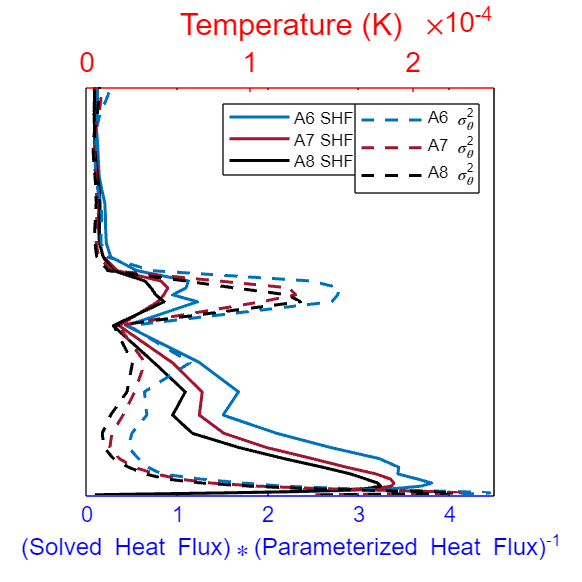

figure;
set(gcf, 'Position', [100, 100, 600, 600]); % Aumentar el tamaño de la figura
% Eje original (eje inferior)
ax1 = axes;
p(1) = plot(ax1,ur1(:,5)./HF1(5),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (km)');
% Personalizar el primer eje
ax1.XColor = 'blue';
ax1.YColor = 'black';
p(2) = plot(ax1,ur2(:,5)./HF2(5),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ax1,ur3(:,5)./HF3(5),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 SHF','A7 SHF','A8 SHF'},'Location', 'north');
xlim(ax1, [0, 4.5]);
xlabel('(Solved Heat Flux)\ast(Parameterized Heat Flux)^{-1}', 'Color', 'b');
% Añadir un segundo eje (eje superior)
ax2 = axes('Position', ax1.Position, 'XAxisLocation', 'top', 'YAxisLocation', 'left', ...
           'Color', 'none');
hold(ax2, 'on');
p(4) = plot(ax2,um1(:,5),ejez./1000,'--', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
p(5) = plot(ax2,um2(:,5),ejez./1000,'--', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(6) = plot(ax2,um3(:,5),ejez./1000,'--', 'LineWidth', 1.5, 'Color','k');hold on;
% Personalizar el segundo eje
ax2.XColor = 'red';
ax2.YTick = []; % Opcional: eliminar las marcas en el eje Y del segundo eje
% % Sincronizar límites en el eje Y para que se alineen visualmente
linkaxes([ax1, ax2], 'y');
% % Crear una sola leyenda combinada para ambos gráficos
legend({'A6 \sigma_{\theta}^2','A7 \sigma_{\theta}^2','A8 \sigma_{\theta}^2'},'Location', 'northeast');
xlim(ax2, [0, 0.00025]);
xlabel('Temperature (K)', 'Color', 'r');
ylim([0, 2]);
hold off
ax1.XAxis.FontSize = 11; % Eje izquierdo
ax2.XAxis.FontSize = 14; % Eje derecho
ax1.YAxis.FontSize = 14;    % Eje X
ax2.YAxis.FontSize = 14;    % Eje X
ax1.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
ax2.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
set(ax1, 'YTick', [])
set(ax2, 'YTick', [])

% print('Figura4E', '-dpng', '-r1000');

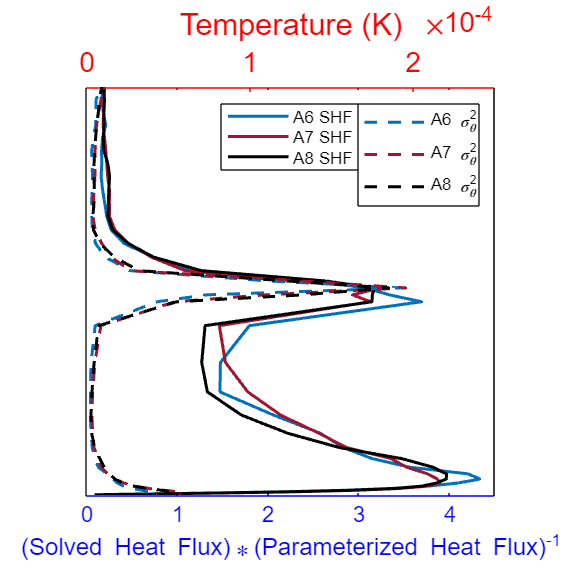

figure;
set(gcf, 'Position', [100, 100, 600, 600]); % Aumentar el tamaño de la figura
% Eje original (eje inferior)
ax1 = axes;
p(1) = plot(ax1,ur1(:,8)./HF1(8),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (km)');
% Personalizar el primer eje
ax1.XColor = 'blue';
ax1.YColor = 'black';
p(2) = plot(ax1,ur2(:,8)./HF2(8),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ax1,ur3(:,8)./HF3(8),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 SHF','A7 SHF','A8 SHF'},'Location', 'north');
xlim(ax1, [0, 4.5]);
xlabel('(Solved Heat Flux)\ast(Parameterized Heat Flux)^{-1}', 'Color', 'b');
% Añadir un segundo eje (eje superior)
ax2 = axes('Position', ax1.Position, 'XAxisLocation', 'top', 'YAxisLocation', 'left', ...
           'Color', 'none');
hold(ax2, 'on');
p(4) = plot(ax2,um1(:,8),ejez./1000,'--', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
p(5) = plot(ax2,um2(:,8),ejez./1000,'--', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(6) = plot(ax2,um3(:,8),ejez./1000,'--', 'LineWidth', 1.5, 'Color','k');hold on;
% Personalizar el segundo eje
ax2.XColor = 'red';
ax2.YTick = []; % Opcional: eliminar las marcas en el eje Y del segundo eje
% % Sincronizar límites en el eje Y para que se alineen visualmente
linkaxes([ax1, ax2], 'y');
% % Crear una sola leyenda combinada para ambos gráficos
legend({'A6 \sigma_{\theta}^2','A7 \sigma_{\theta}^2','A8 \sigma_{\theta}^2'},'Location', 'northeast');
xlim(ax2, [0, 0.00025]);
xlabel('Temperature (K)', 'Color', 'r');
ylim([0, 2]);
hold off
ax1.XAxis.FontSize = 11; % Eje izquierdo
ax2.XAxis.FontSize = 14; % Eje derecho
ax1.YAxis.FontSize = 14;    % Eje X
ax2.YAxis.FontSize = 14;    % Eje X
ax1.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
ax2.Position = [0.15, 0.15, 0.7, 0.7]; % [left, bottom, width, height]
set(ax1, 'YTick', [])
set(ax2, 'YTick', [])

% print('Figura4F', '-dpng', '-r1000');


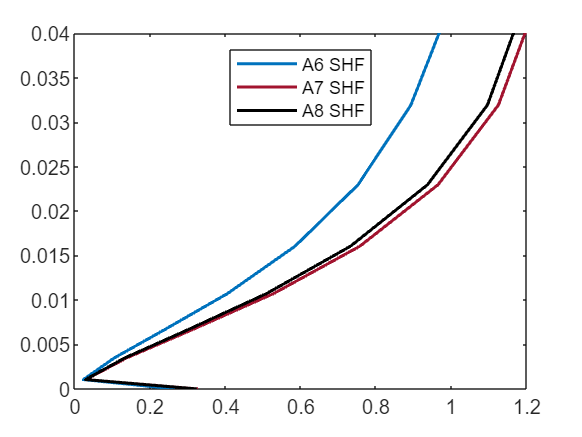

ur1=[HF1;ur1];
ur2=[HF2;ur2];
ur3=[HF3;ur3];
ej=[0];
ejez=[ej; ejez'];
figure;
% Eje original (eje inferior)
p(1) = plot(ur1(:,8),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (km)');
% Personalizar el primer eje
p(2) = plot(ur2(:,8),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ur3(:,8),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 SHF','A7 SHF','A8 SHF'},'Location', 'north');
% xlim([0, 4.5]);
ylim([0, 0.04]);

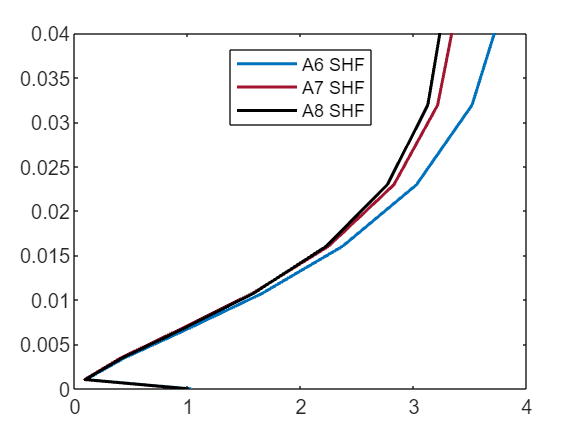


figure;
% Eje original (eje inferior)
p(1) = plot(ur1(:,5),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (km)');
% Personalizar el primer eje
p(2) = plot(ur2(:,5),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ur3(:,5),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 SHF','A7 SHF','A8 SHF'},'Location', 'north');
% xlim([0, 4.5]);
ylim([0, 0.04]);

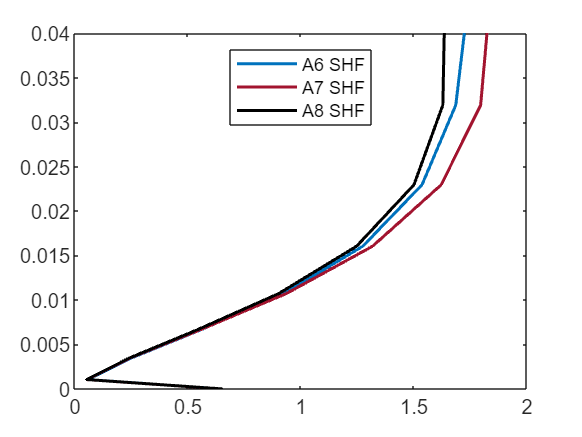


figure;
% Eje original (eje inferior)
p(1) = plot(ur1(:,2),ejez./1000,'-', 'LineWidth', 1.5, 'Color', '#0072BD');hold on;
% ylabel(ax1, 'Height (km)');
% Personalizar el primer eje
p(2) = plot(ur2(:,2),ejez./1000,'-', 'LineWidth', 1.5, 'Color','#A2142F');hold on;
p(3) = plot(ur3(:,2),ejez./1000,'-', 'LineWidth', 1.5, 'Color','k');hold on;
legend({'A6 SHF','A7 SHF','A8 SHF'},'Location', 'north');
% xlim([0, 4.5]);
ylim([0, 0.04]);